1. Using Secant method, write a MATLAB program to find the roots of 

the following equations with an error tolerance ϵ = 10−6.

(a) x3 − x2 − x − 1 = 0.

(b) cos(x) =1/2 + sin(x).

Determine the initial approximations x0 and x1 to find the root.

% Question 1
format long


x = 0;
err= 1;
fplot(@(x) f1(x),[-10,10]);

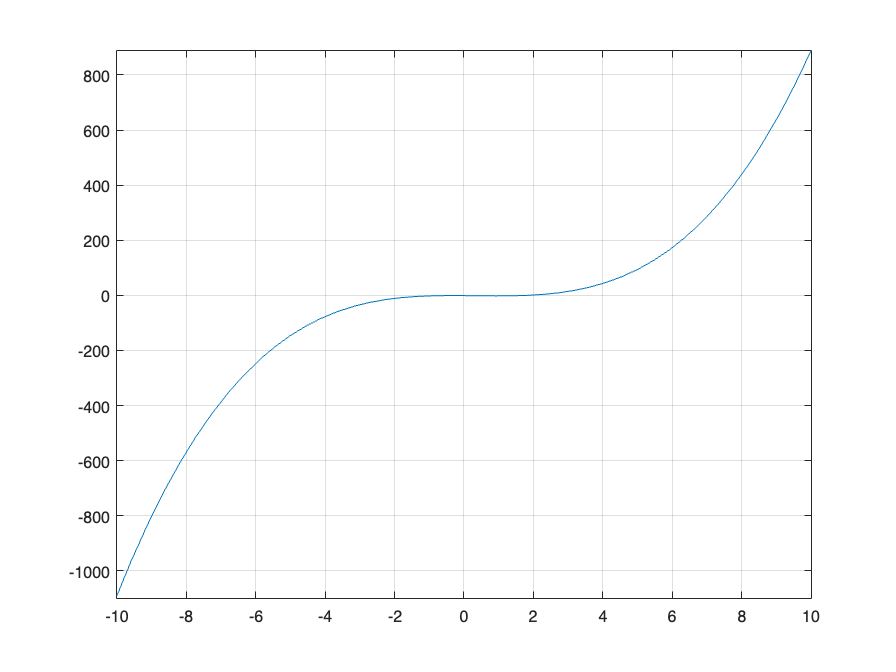

grid ON;


x1 = 10; x0 = -10;
while(abs(x1-x0) > 1e-6)
    x2 = x1 - f1(x1)*(x1-x0)/(f1(x1) - f1(x0));
    x0 = x1;
    x1 = x2;
    err = f1(x2);
end
ans = x2

ans =    1.839286755214160


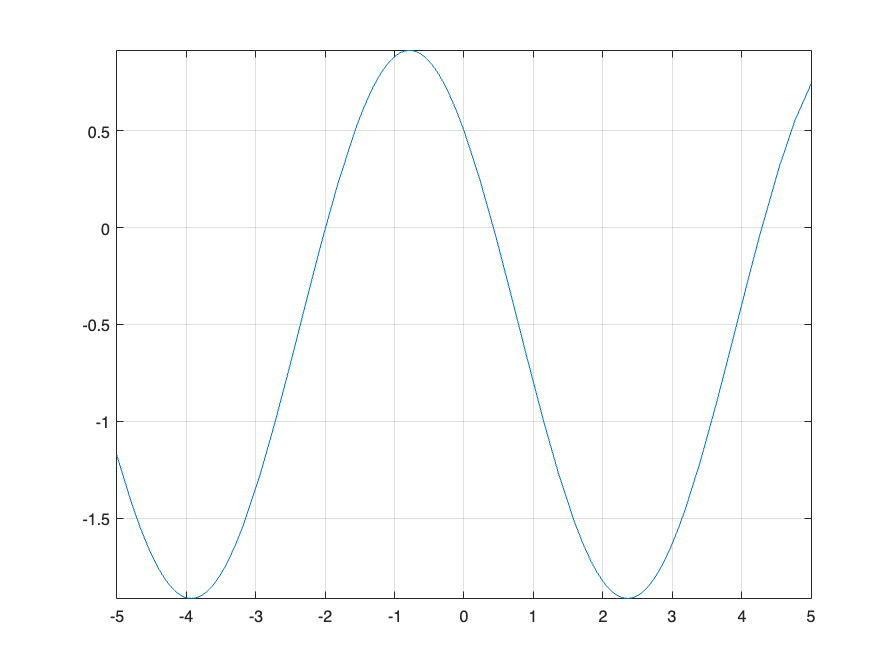

%Question 2

x = 0;
err= 1;
iter = 0;
fplot(@(x) f2(x));
grid ON;


x1 = 2; x0 = 0;
while(abs(x1-x0) >1e-6)
    x2 = x1 - f2(x1)*(x1-x0)/(f2(x1) - f2(x0));
    x0 = x1;
    x1 = x2;
    err = f2(x2);
end
ans = x2

ans =    0.424031039649516


function ret = f1(x)
    ret = x^3 - x^2 - x -1;
end

function ret = f2(x)
    ret = cos(x) - 1/2 - sin(x);
end